# Instituto Tecnológico de Aeronaútica

### Aluno: Eduardo Bezerra Robalinho Dantas da Gama;

### Professor: Dr. Francisco Alex Correia Monteiro

Usar BVP4c para resolver uma edp, a partir de um chute inicial

- a ideia é achar uma função (ou sistema) que resolva a edp num dado contorno

- Resolver um PVC de forma que o residuo no contorno seja o menor possível

Tamanho do intervalo:

L=100;

Parâmetros do sistema de equações:

D=5000;
U=100;
k=2;

Condições de contorno não homôgeneas:

l_cc=100;
r_cc=0;

Criação da malha com os valores iniciais:

xmesh = linspace(0,L,50);
solinit = bvpinit(xmesh, @guess);

Retorna:

- uma struct com sol.x sendo o domínio no que for avaliado as funções

- sol.y é uma matriz com cada linha sendo os valores da função nos pontos da sol.x

sol = bvp4c(@(x,y) sist_edp(x,y,k,D,U),@(yl,yr) res_bond(yl,yr,D,U,l_cc,r_cc), solinit);

Plot dos gráficos:

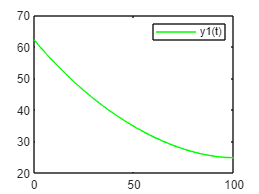

figure(1)
plot(sol.x, sol.y(1,:), '-g')
legend('y1(t)'); 

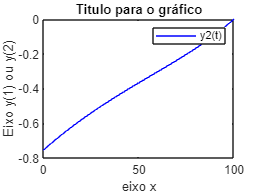

figure(2)
plot(sol.x, sol.y(2,:), '-b')
title('Titulo para o gráfico')
xlabel('eixo x');
ylabel('Eixo y(1) ou y(2)');
legend('y2(t)'); 

Função com o chute inicial para estimar paulatinamente a função:

function g = guess(x) % o chute é da forma g(x) =[a(x) e b(x)]
g = [0 0];
end

Função de resíduos para estimar os valores do contorno:

function res = res_bond(yl,yr,D,U,l_cc,r_cc)
    res=[yl(1) - (D/U)*yl(2) - l_cc , yr(2)-r_cc];
end

Função com a EDP em forma de matriz (igual ao ode45):

function dxdy = sist_edp(x,y,k,D,U)
    dxdy=[y(2), (k*y(1) + U*y(2))/D];
end